# **SPR Biosensor : 2D Grating**

           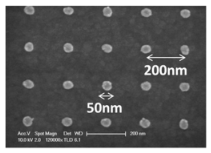        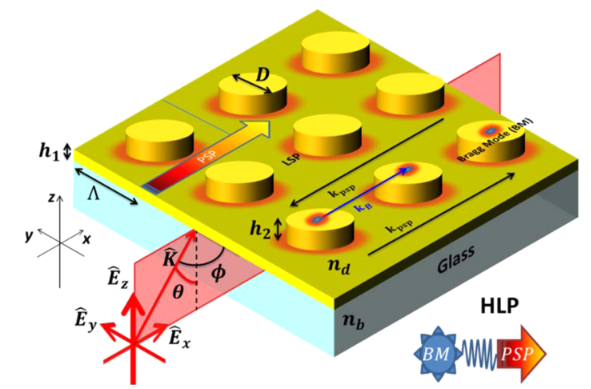

[Hybrid Plasmonic Mode by Resonant Coupling of Localized Plasmons to Propagating Plasmons in a Kretschmann Configuration](https://hal-iogs.archives-ouvertes.fr/hal-01307382) 

Mitradeep Sarkar, Mondher Besbes, Julien  Moreau, Jean-François Bryche, Aurore Olivéro, Grégory Barbillon,  Anne-Lise Coutrot, Bernard Bartenlian, Michael Canva                           

 *ACS photonics*, 2015, 2 (2), pp.237-245.

## Data 

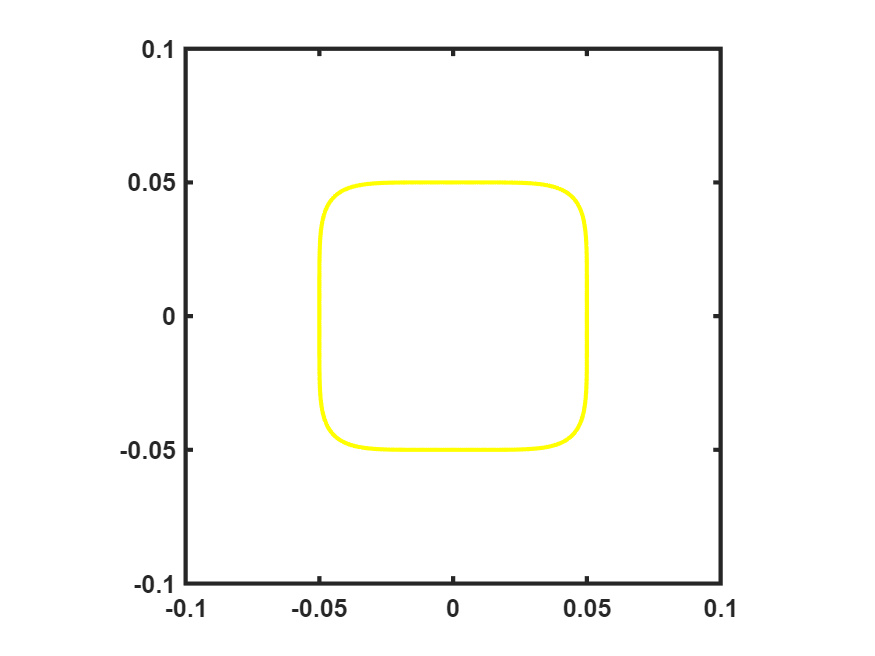

% Refractive indices
n_H2O = 1.333;
%  {supstrat {grating} layers substrat}
index = {n_H2O , {IndexVal('Au') n_H2O}, IndexVal('Au'), IndexVal('SF10')}; 
%
% Geometry (µm)
h1 = 0.03; % Grating thickness (µm)
h2 = 0.03; % Gold layer thickess
dx = 0.2;  % Period x-axis 
dy = 0.2;  % Period y-axis
a = 0.05;  % Half the width of the nanoparticle x-axis
b = 0.05;  % Half the width of the nanoparticle y-axis
%
% SuperFormula parameters
% mn = [m, n1, n2, n3]  ; ab = [rx ry]
% [4 1 1 1] : Diamond
% [4 2 2 2] : Circle or ellipse
% [4 n n n] : n>2 rounded square or rectangle 
% [3 n 2*n 2*n] : rounded triangle n>1
% mn = 4 : Rectangle or square 
%
geom = SetGeom('dx',dx,'dy',dy,'hc',[h1, h2],...
               'mn',{[4 6 6 6]  []},'ab',{[a b] []},...
               'npx',{[41 2] ,2},'npy',{[41 2] ,2},'npz',{2 , 2},'Plot',1);

## Spectrum Computation versus incident angle

% Incident Plane Wave
lambda = .85;                       % Wavelength(µm)
theta = linspace(50,70,41)*pi/180;  % Incident angle (rd)
inc = -1;                           % inc = -1: from down, +1: from top
%
% Spectrum Computation versus incident angle (theta) for a defined wavelength
tic
[R_tm,T_tm,R_te,T_te] = Spectrum(index,geom,lambda,theta,inc,'mx',8,'my',8,'SymY',0); 
t = toc

t = 5.1638

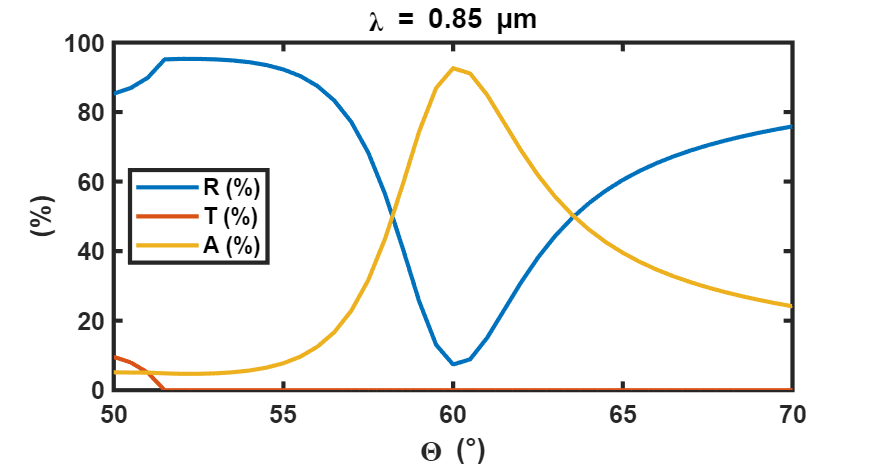

%
% Plot Reflection versus incident angle in TM polarisation
figure('Position',[300  300  560  300]), 
PlotCoefRTA(lambda,theta,R_tm,T_tm,1-R_tm-T_tm), 

## Field Computation for a defined polarization (pol = 0 (TE) or 2 (TM) )

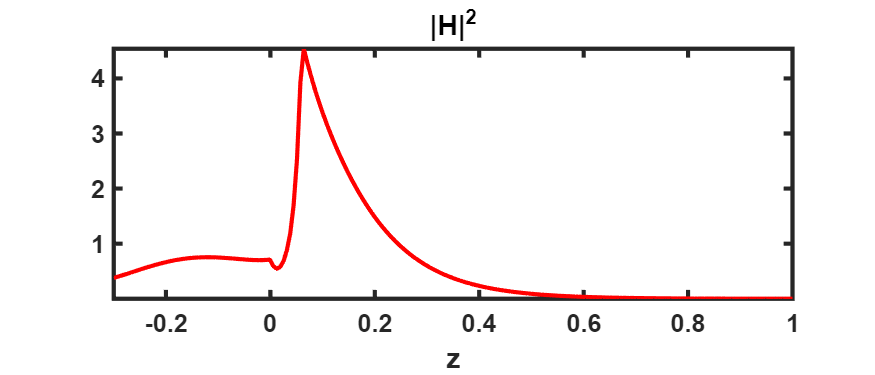

lambda = 0.85; 
theta = 60*pi/180; 
inc = -1;           % inc = -1: from down, +1: from up
%
% S-matrix calculation
s = Spectrum(index,geom,lambda,theta,inc,'mx',8,'my',8);
%
% Field calculation
pol = 2;                                 % 0: TE, 2: TM
[x,y,z] = deal(0,0,linspace(-.3,1,201)); % along z-axis
[E,H] = CalculFieldFMM(s,x,y,z,pol);         

% Plot Field distribution
figure('Position',[300  300  560  240]), 
VisuFieldFMM(sum(abs(H).^2,2),x,y,z), axis tight,title('|H|^2') 

## Field Distribution at plan (xOz)

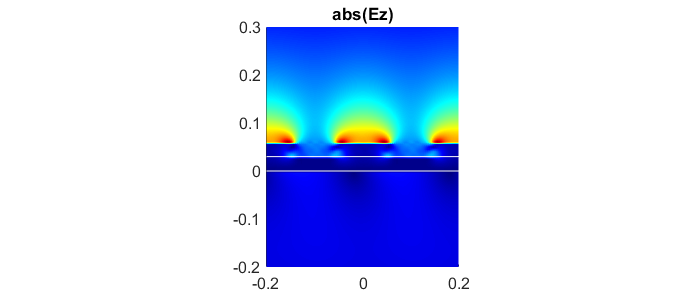

% Field calculation
pol = 2;  % 0: TE, 2: TM
[x,y,z] = deal(linspace(-dx,dx,100),0,linspace(-.2,.3,101)); % (xoz) 
[E,H] = CalculFieldFMM(s,x,y,z,pol);         

% Plot Field distribution
figure('Position',[300  300  560  240]), hold on
VisuFieldFMM(abs(E(:,3)),x,y,z), axis tight,title('abs(Ez)') 
plot([min(x) max(x)],[0 0],'w',[min(x) max(x)],[h2 h2],'w') % Gold layer

## Field Distribution at plan (xOy)

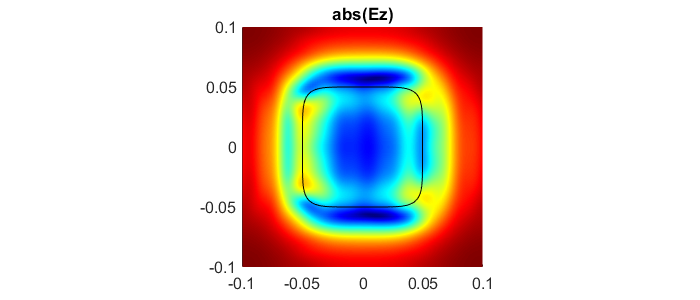

% Field calculation
pol = 2;  % 0: TE, 2: TM
[x,y,z] = deal(linspace(-dx/2,dx/2,100),linspace(-dy/2,dy/2,101),h1/2+h2); % (xoy) 
[E,H] = CalculFieldFMM(s,x,y,z,pol);         

% Plot Field distribution
figure('Position',[300  300  560  240]), hold on
VisuFieldFMM(abs(E(:,3)),x,y,z), axis tight,title('abs(Ez)') 
plot(s.Mesh(2).xv,s.Mesh(2).yv,'k') % Nanoparticle

## Test of convergence

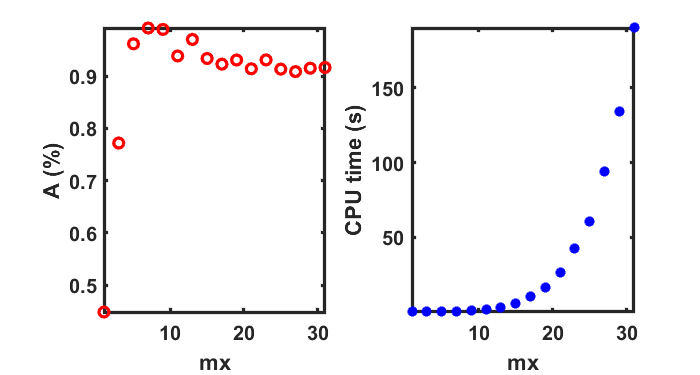

% Incident Plane Wave
lambda = 0.85; 
theta = 60*pi/180; 
inc = -1;           % inc = -1: from down, +1: from up
%
TabM = 1:2:31;      % Number of Fourier terms
[A,t] = deal(zeros(size(TabM)));
%
figure('Position',[300  300  560  300]), hold on
%
for k = 1:length(TabM)
    mxy = TabM(k);
    tic, s = Spectrum(index,geom,lambda,theta,inc,'mx',mxy,'my',mxy,'SymY',0); t(k) = toc;
    % A=1-R-T
    if length(s.R_tem) == 1  % SymY = 0 or 1
        A(k) = 1-(s.R_tem)-(s.T_tem);
    else  % SymY = 2 (default value)
        A(k) = 1-(s.R_tem(1)+s.R_tem(2))-(s.T_tem(1)+s.T_tem(2));
    end
    subplot(121),hold on, PlotCourbe(TabM(k),A(k),'mx','A (%)','','or'), drawnow
    subplot(122),hold on, PlotCourbe(TabM(k),t(k),'mx','CPU time (s)','','*b'), drawnow
end